# Reference

Edge, Graham. *Imaging fermionic atoms in a quantum gas microscope*. Diss. University of Toronto (Canada), 2017.

# Mathieu Functions Characteristic

For 1D periodic structure, one can solve for the energy bands by computing Mathieu function characteristics.


$$E_{n,max} = E_R\left (a_n
\left( \frac{V_L}{4E_R} \right)+\frac{V_L}{2E_R}\right) \\
E_{n,min} = E_R\left (b_{n+1}\left(\frac{V_L}{4E_R}\right)+\frac{V_L}{2E_R}\right)$$


clear
clc

NumBand = 10;
MaxDepth = 20;
StepDepth = 2;

Depth = 0:StepDepth:MaxDepth;
NumDepth = length(Depth);
EBandMin = nan(NumBand,NumDepth);
EBandMax = nan(NumBand,NumDepth);
NumBound = 1;

tic
for i = 1:NumDepth
    EBandMin(:,i) = eiga(NumBand-1,Depth(i)/4,'all')+Depth(i)/2;
    EBandMax(:,i) = eigb(NumBand,Depth(i)/4,'all')+Depth(i)/2;
%     if EBandMax(:,i)
end
toc

Elapsed time is 0.737694 seconds.


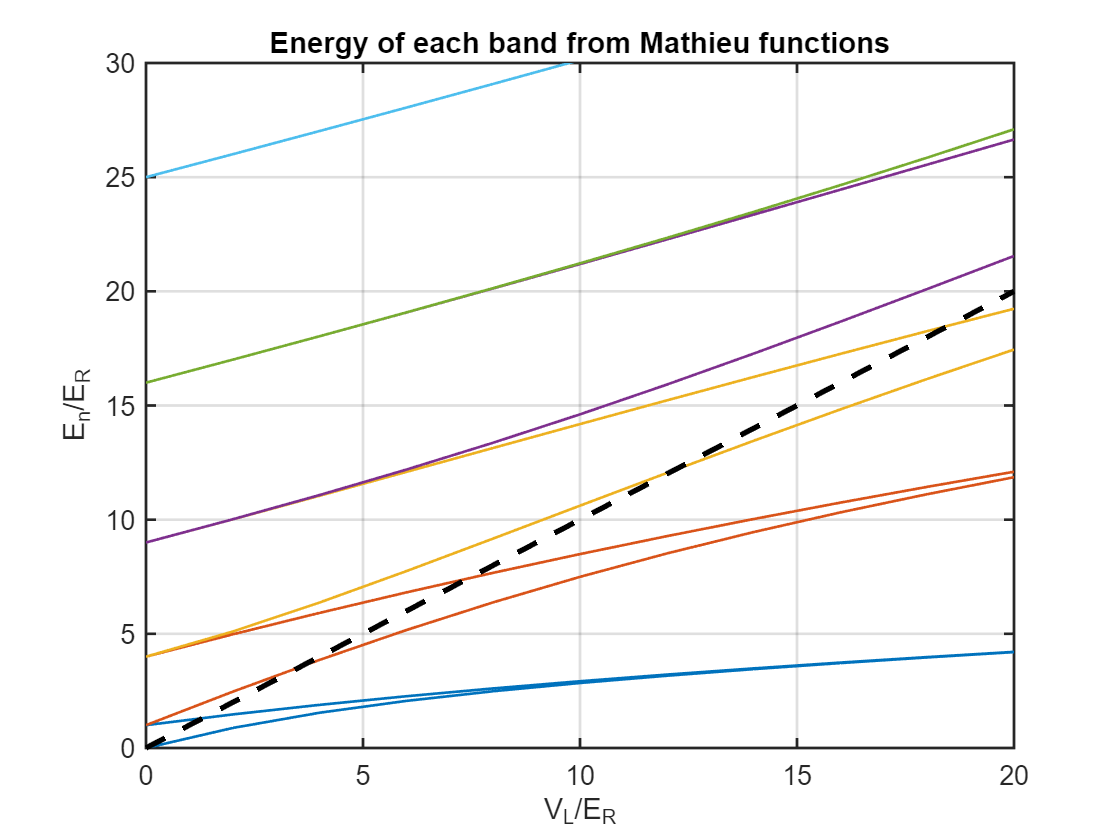


figure
box on
grid on
hold on
set(gca,'LineWidth',1)
for i = 1:NumBand
    plot(Depth',EBandMin(i,:),"SeriesIndex",i,"LineWidth",1)
    plot(Depth',EBandMax(i,:),"SeriesIndex",i,"LineWidth",1)
end
plot(Depth',Depth','k--','LineWidth',2)
xlim([0 MaxDepth])
ylim([0 MaxDepth+10])
xlabel('V_L/E_R')
ylabel('E_n/E_R')
title('Energy of each band from Mathieu functions')

# Band structure numerical simulation

Band structure of a simple 1D lattice.